clear all
clc
close all

cs=crystalSymmetry('432')

 
cs = crystalSymmetry
 
  symmetry: 432    
  elements: 24     
  a, b, c : 1, 1, 1
 



hkl=Miller(1,1,1,cs)

 
hkl = Miller (432)
  h k l
  1 1 1


## Plotting the normal and the traces of the planes


figure
hold on
% the normal direction
plot(hkl,'upper','labeled')
hold off


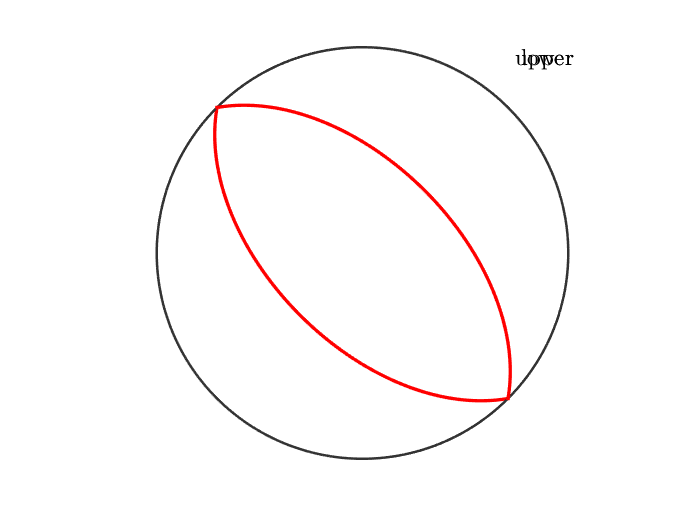

figure
hold on
% the trace of the corresponding lattice plane
plot(hkl,'plane','linecolor','r','linewidth',2)
hold off

## Define orientation using Miller indices

n=Miller(0,0,1,'hkl',cs) % plane normal || ND

 
n = Miller (432)
  h k l
  0 0 1


b=Miller(9,1,0,'uvw',cs) % direction parallel to RD

 
b = Miller (432)
  u v w
  9 1 0



ori=orientation.byMiller(n,b)

 
ori = orientation (432 → xyz)
 
  Bunge Euler angles in degree
    phi1    Phi   phi2
  353.66      0      0
 


hkl1=ori*hkl

 
hkl1 = vector3d
        x        y        z
  1.10432 0.883452        1



hkl11=Miller(hkl1.x,hkl1.y,hkl1.z,cs)

 
hkl11 = Miller (432)
       h      k      l
  1.1043 0.8835      1


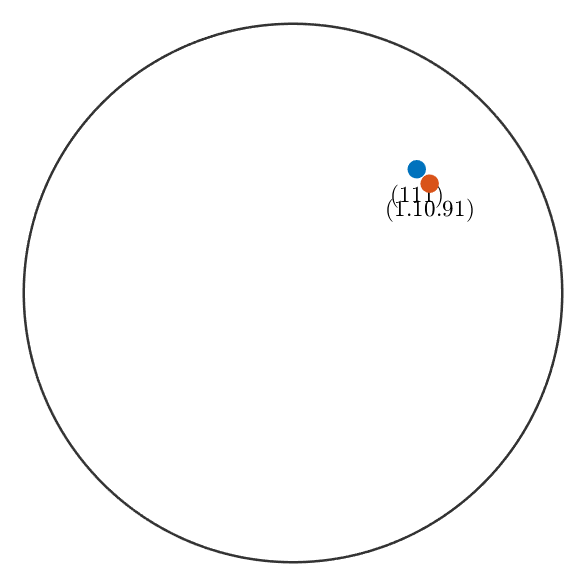


%plotx2north
figure
% the normal direction
plot(hkl,'upper','labeled')
hold on
plot(hkl11,'upper','labeled')
hold off


ori.matrix

ans =     0.9939    0.1104         0
   -0.1104    0.9939         0
         0         0    1.0000


methods(ori)

Methods for class orientation:

BCV                        Euler                      KLCV                       LSCV                       Rodrigues                  accumarray                 addOption                  angle                      angle_outer                axis                       bingham_test               calcAngleDistribution      calcBinghamODF             calcCluster                calcDensity                calcFourierODF             calcInvTaylor              calcKernel                 calcKernelODF              calcMIndex                 calcTensor                 calcVoronoi                calcVoronoiVolume          cat                        char                       cross                      crossCorrelation           ctranspose                 cubochoric                 display                    doHClustering              dot                        dot_angle                  dot_outer                  double                     end                    

## (hkl) planes of random orientations

hkl=Miller(1,0,0,cs)

 
hkl = Miller (432)
  h k l
  1 0 0


r_ori=orientation.rand(100000,cs)

 
r_ori = orientation (432 → xyz)
  size: 100000 x 1
 
  show Euler angles
 


rhkl=r_ori*hkl

 
rhkl = vector3d
 size: 100000 x 1
 
  show vectors
 


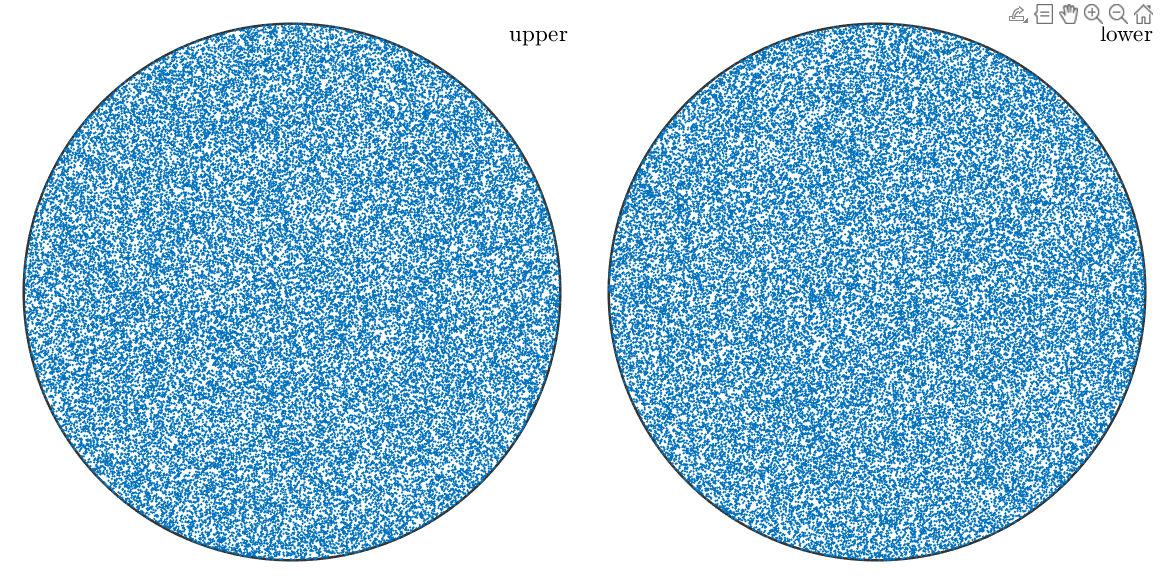

figure
plot(rhkl)